

gamma = 1.4

gamma = 1.4000

scalefactor = 0.00377472

scalefactor = 0.0038

R = 0.6638*scalefactor; %m
M_freestream = 3.4;
theta = 70; % degrees

## Body geometry calculations

xs = R*cosd(90-theta);
ys = R*sind(90-theta);
c = ys+xs^2/ys;
m = -xs/ys;

body_x = linspace(0, R, 100)

body_x =          0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012


body_y = zeros(1,length(body_x));


for i = 1:length(body_x)
    if body_x(i) > xs 
        body_y(i) = sqrt(R^2-body_x(i)^2);
    else
        body_y(i) = m*body_x(i)+c;
    end
end



## Shock Calculations

R_c = R*(1.143*exp(0.54/((M_freestream-1)^1.2))); % m
shock_offset = R*0.143*exp(3.24/(M_freestream^2)) % m

shock_offset = 4.7422e-04


beta1 = 70%beta(M_freestream, theta, gamma, 0)

beta1 = 70

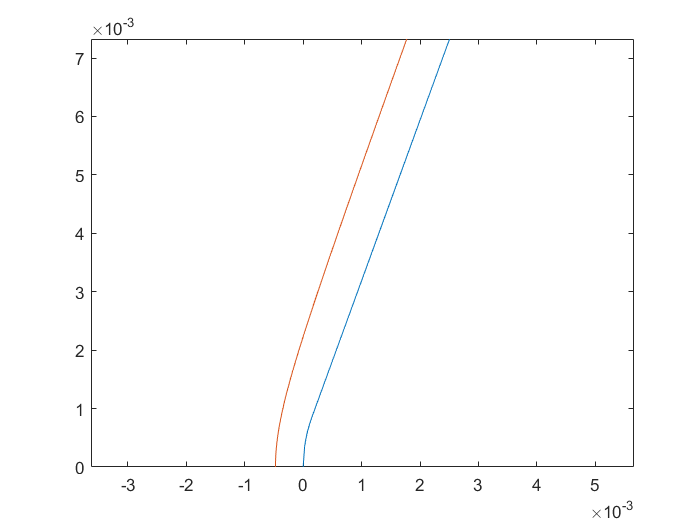



shock_y = linspace(0,max(body_y),100);
shock_x = R + shock_offset - R_c.*(cotd(beta1)).^2.*((1+shock_y.^2.*(tand(beta1).^2)/(R_c.^2)).^0.5-1);

body_x = -(body_x - R);
shock_x = -(shock_x - R);



plot(body_x, body_y)
axis equal
hold on 
plot(shock_x,shock_y)

function Beta=beta(M,theta,gamma,n)
theta=theta*pi/180;             % convert to radians
mu=asin(1/M);                   % Mach wave angle
c=tan(mu)^2;
a=((gamma-1)/2+(gamma+1)*c/2)*tan(theta);
b=((gamma+1)/2+(gamma+3)*c/2)*tan(theta);
d=sqrt(4*(1-3*a*b)^3/((27*a^2*c+9*a*b-2)^2)-1);
Beta=atan((b+9*a*c)/(2*(1-3*a*b))-(d*(27*a^2*c+9*a*b-2))/(6*a*(1-3*a*b))*tan(n*pi/3+1/3*atan(1/d)))*180/pi;


end

